# Data Process

## Raw Data



% Raw_Data = readtable('Raw_Data.csv');
% Connection = readtable('vncs_peng_contra_highres.csv');
% Regions = Connection.Var1;
% 
% 
% 
% for i = 1:length(Regions)
%     iRegions{i, 1} = ['i', Regions{i}];
%     cRegions{i, 1} = ['c', Regions{i}];
% end
% 
% AllRegions = [iRegions; cRegions];
% 
% Data = table();
% Data.Group = Raw_Data.Var1;
% Raw_Regions = transpose(Raw_Data.Properties.VariableNames(2:end));
% 
% 
% for i = 1:length(AllRegions)
%     AllRegionsTemp = AllRegions{i};
%     Loc = find(strcmp(Raw_Regions,AllRegionsTemp)==1);
%     DataTemp = Raw_Data(:,Loc+1);
%     eval(['Data.', AllRegionsTemp, '=', 'table2array(Raw_Data(:,Loc+1));']);
% end
% writetable(AllRegions,'RegionList.csv')
% writetable(Data,'Data.csv')
% 

## Connection

% clear
% iConnection_Raw = readtable('vncs_peng_ipsi_highres.csv');
% cConnection_Raw = readtable('vncs_peng_contra_highres.csv');
% 
% iConnection = table2array(iConnection_Raw(:,2:end));
% cConnection = table2array(cConnection_Raw(:,2:end));
% Connection = [iConnection, cConnection; cConnection, iConnection];
% 
% writematrix(Connection,'Connection.csv')

## Sort

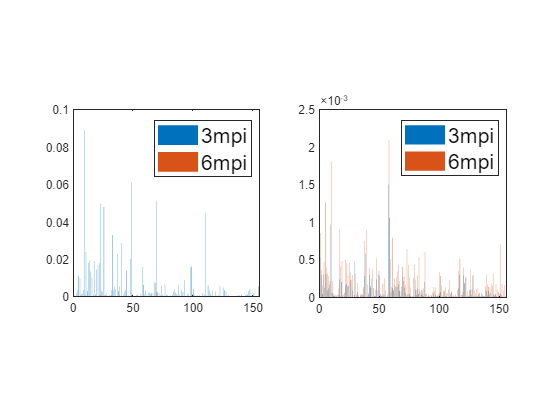

clear
PathData = readtable('C:\Yuanxi\MatlabCodes\pathology transmission\PFF GCI\Data.csv');
% Snca = readtable('/data/Snca.csv');
Weight = readtable('C:\Yuanxi\MatlabCodes\pathology transmission\PFF GCI\Connection.csv');
Connection = table2array(Weight);

GCI_3mpi_Raw = PathData(strcmp(PathData.Group, 'GCI_3mpi'),:);
GCI_6mpi_Raw = PathData(strcmp(PathData.Group, 'GCI_6mpi'),:);

GCI_3mpi_Raw = removevars(GCI_3mpi_Raw,'Group');
GCI_6mpi_Raw = removevars(GCI_6mpi_Raw,'Group');

Time = [3,6];
GCIMean(1,:) = mean(table2array(GCI_3mpi_Raw),'omitnan');
GCIMean(2,:) = mean(table2array(GCI_6mpi_Raw),'omitnan');

PFF_3mpi_Raw = PathData(strcmp(PathData.Group, 'PFF_3mpi'),:);
PFF_6mpi_Raw = PathData(strcmp(PathData.Group, 'PFF_6mpi'),:);

PFF_3mpi_Raw = removevars(PFF_3mpi_Raw,'Group');
PFF_6mpi_Raw = removevars(PFF_6mpi_Raw,'Group');

Time = [3,6];
PFFMean(1,:) = mean(table2array(PFF_3mpi_Raw),'omitnan');
PFFMean(2,:) = mean(table2array(PFF_6mpi_Raw),'omitnan');

subplot(1,2,1)
bar(transpose(GCIMean),'DisplayName','GCIMean')
legend({'3mpi','6mpi'},'Fontsize',16)
axis square

subplot(1,2,2)
bar(transpose(PFFMean),'DisplayName','PFFMean')
legend({'3mpi','6mpi'},'Fontsize',16)
axis square

## coefficient of variation

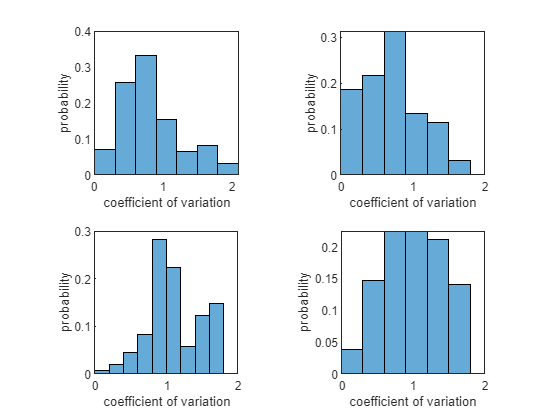

for i = 1:156
    COV(1,i) = std(table2array(PFF_3mpi_Raw(:,i)),'omitnan')/mean(table2array(PFF_3mpi_Raw(:,i)),'omitnan');
    COV(2,i) = std(table2array(PFF_6mpi_Raw(:,i)),'omitnan')/mean(table2array(PFF_6mpi_Raw(:,i)),'omitnan');
    COV(3,i) = std(table2array(GCI_3mpi_Raw(:,i)),'omitnan')/mean(table2array(GCI_3mpi_Raw(:,i)),'omitnan');
    COV(4,i) = std(table2array(GCI_6mpi_Raw(:,i)),'omitnan')/mean(table2array(GCI_6mpi_Raw(:,i)),'omitnan');
end


for i = 1:4
    subplot(2,2,i)
    histogram(COV(i,:),'Normalization','probability')
    xlabel('coefficient of variation')
    ylabel('probability')
    
    axis square
end

clearvars GCI_3mpi_Raw GCI_6mpi_Raw PathData PFF_3mpi_Raw PFF_6mpi_Raw Weight

## Fit

BrainList = readtable('RegionList.csv','ReadVariableNames',false);
BrainList = table2cell(BrainList);
Diag_Array = ones(size(BrainList));
Diag_Mat = diag(Diag_Array);
Diag_Mat = ~Diag_Mat;
Connection_AfterProcessing = Connection.*Diag_Mat;
clearvars Diag_Array Diag_Mat Connection

Connection_Eigen = Connection_AfterProcessing/max(eig(Connection_AfterProcessing));
OutDegree = sum(Connection_Eigen,2);
Connection = diag(OutDegree)-Connection_Eigen;
clearvars Connection_AfterProcessing Connection_Eigen OutDegree

# fit for GCI


x0_Val = linspace(0.001,1,100);
C_all = linspace(0.01,10,100);
GCI_Real = transpose(GCIMean);
Predict = {};
tic
for x0_Num = 1:length(x0_Val)
    x0 = zeros(156,1);
    x0(19) = x0_Val(x0_Num);


    for C_Num = 1:length(C_all)
        Predict{C_Num}(:,1) = expm(-C_all(C_Num)*3*Connection)*x0;
        Predict{C_Num}(:,2) = expm(-C_all(C_Num)*6*Connection)*x0;
        PredictTemp = Predict{C_Num};
        for Time = 1:2
            MSEResult(x0_Num,C_Num,Time) = sum((PredictTemp(:,Time)-GCI_Real(:,Time)).^2)/156;
        end
    end
end
toc

Elapsed time is 41.283905 seconds.


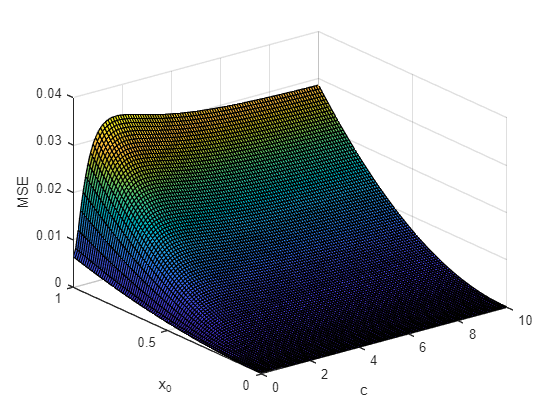

for x0_Num = 1:length(x0_Val)   
    for C_Num = 1:length(C_all)
        MSEMean(x0_Num,C_Num) = mean(MSEResult(x0_Num,C_Num,:));
    end
end
figure
surf(C_all,x0_Val,MSEMean)

xlabel('c')
ylabel('x_0')
zlabel('MSE')

min(min(MSEMean))

ans = 8.1151e-05

[loc1,loc2] = find(MSEMean==min(min(MSEMean)))

loc1 = 3

loc2 = 52

x0_final = x0_Val(loc1)

x0_final = 0.0212

c_final = C_all(loc2)

c_final = 5.1564

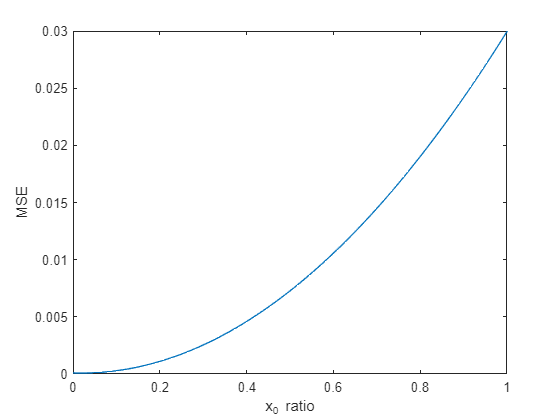

Real_GCI = transpose(log10(GCIMean));
C_all = linspace(0.01,10,100);
% C = C_all(5);
C = C_all(52);

x0 = zeros(156,1);
x0(19) = 1;
x0exp = -6:1:0;
x0exp = 10.^x0exp;
x0exp = [0 x0exp];
x0try = [];
for i = 1:(length(x0exp)-1)
    x0exptemp = linspace(x0exp(i),x0exp(i+1),100);
    x0try = [x0try;x0exptemp'];
end

GCIHere = transpose(GCIMean);
for i = 1:length(x0try)
    LogPredict{i}(:,1) = log10(expm(-C*3*Connection)*x0try(i)*x0);
    LogPredict{i}(:,2) = log10(expm(-C*6*Connection)*x0try(i)*x0);
end


for i = 1:length(x0try)
    PredictTemp = 10.^(LogPredict{i});
    for Time = 1:2
        Variation(i,Time) = sum((PredictTemp(:,Time)-GCIHere(:,Time)).^2)/156;
    end
end

MeanVariation = mean(Variation,2);
plot(x0try,MeanVariation)
xlabel('x_0 ratio')
ylabel('MSE')

min(MeanVariation)

ans = 8.0938e-05

x0ratio_bestloc = find(MeanVariation==min(MeanVariation))

x0ratio_bestloc = 510

x0ratio_best = x0try(x0ratio_bestloc)

x0ratio_best = 0.0182

GCIMean = transpose(GCIMean);

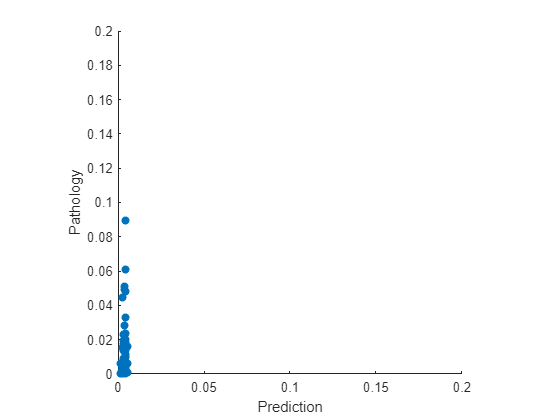

LogPredictResult = LogPredict{x0ratio_bestloc};
PredictResult = 10.^(LogPredictResult);
LogGCIMean = log10(GCIMean);

figure
scatter(PredictResult(:,1),GCIMean(:,1),'filled')
axis([0 0.2,0 0.2])
% axis([0 1,0 1])
xlabel('Prediction')
ylabel('Pathology')
axis square

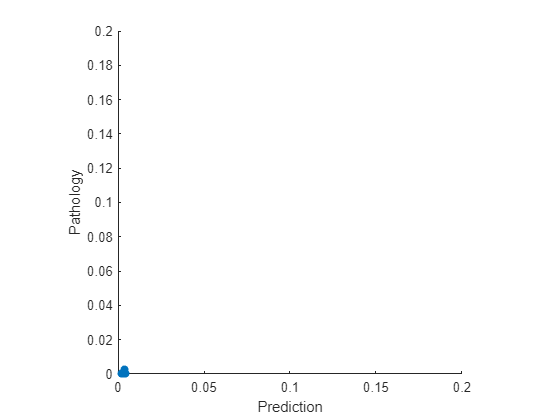

figure
scatter(PredictResult(:,2),GCIMean(:,2),'filled')
axis([0 0.2,0 0.2])
xlabel('Prediction')
ylabel('Pathology')
% axis([0 1,0 1])

axis square

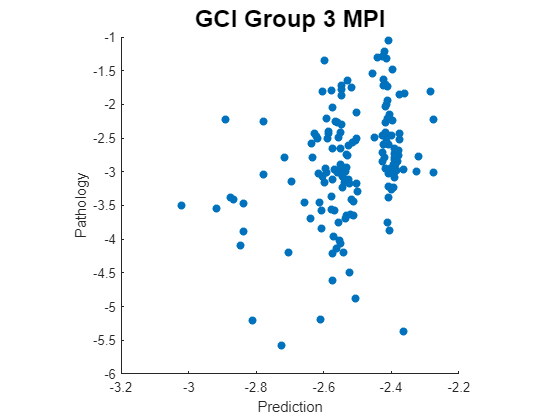

figure
scatter(LogPredictResult(:,1),LogGCIMean(:,1),'filled')
% axis([0 0.2,0 0.2])
% axis([0 1,0 1])
xlabel('Prediction')
ylabel('Pathology')
title('GCI Group 3 MPI','FontSize',18)
axis square

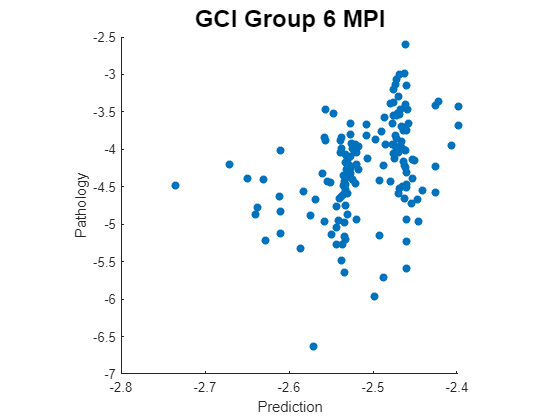

figure
scatter(LogPredictResult(:,2),LogGCIMean(:,2),'filled')
% axis([0 0.2,0 0.2])
% axis([0 1,0 1])
title('GCI Group 6 MPI','FontSize',18)
xlabel('Prediction')
ylabel('Pathology')

axis square

MPI3 = [LogPredictResult(:,1),LogGCIMean(:,1)];
MPI6 = [LogPredictResult(:,2),LogGCIMean(:,2)];
[MPI3_Row,MPI3_Col] = size(MPI3);
FalseLoc = [];
for i = 1:MPI3_Row
    for j = 1:MPI3_Col
        if MPI3(i,j) == inf || MPI3(i,j) == -inf || isnan(MPI3(i,j))
            FalseLoc = [FalseLoc;i];
        end
    end
end
MPI3(FalseLoc,:) = [];
[MPI6_Row,MPI6_Col] = size(MPI6);
FalseLoc = [];
for i = 1:MPI6_Row
    for j = 1:MPI6_Col
        if MPI6(i,j) == inf || MPI6(i,j) == -inf || isnan(MPI6(i,j))
            FalseLoc = [FalseLoc;i];
        end
    end
end
MPI6(FalseLoc,:) = [];






corrcoef(MPI3)

ans =     1.0000    0.3400
    0.3400    1.0000


corrcoef(MPI6)

ans =     1.0000    0.3891
    0.3891    1.0000
